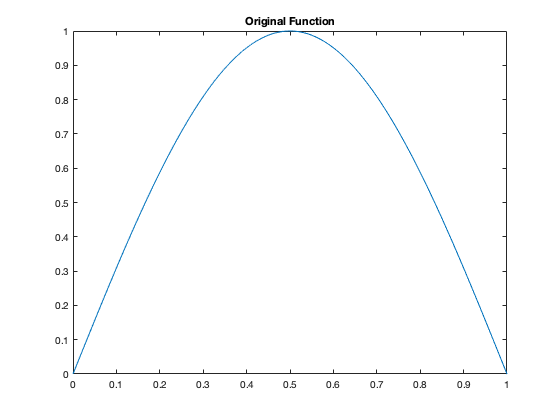

clc; clear; close all;

k = 0.005; % step size
L = 1; % end of original domain
C = 27; % continuation points

phi = @(x) sin(pi*x/L); % function
D = transpose(0:k:L); % domain
phi_D = phi(D); % function values on domain
figure;
plot(D, phi_D);
title("Original Function")

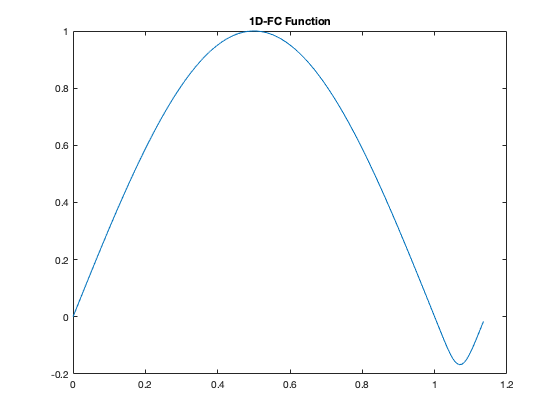


% Interpolation Procedure
d = 10; % degree of interpolation
D_l = D(1:d); % left side of mesh on domain of function
D_r = D(end-d+1:end); % right side of mesh on domain of function
phi_D_l = phi(D_l); % phi values on left side of mesh
phi_D_r = phi(D_r); % phi values on right side of mesh

D_C = transpose(L+k:k:L+C*k); % vector of only continuation points domain
D_l_C = D_l + D_C(end) + k; % left side of mesh of next periods domain after continuation, has values of phi_D_l

D_interpolant = [D_r;D_l_C]; % mesh used for interpolation
phi_interpolant = [phi_D_r; phi_D_l]; % function values used for interpolation
w = barycentric_weights([D_r;D_l_C]); % barycentric weights dependent on interpolation mesh
phi_C = barycentric_compute_func(w, D_interpolant, phi_interpolant, D_C); % continuation values using barycentric interpolation

D_FC = [D; D_C]; % final continued domain
phi_FC = [phi_D; phi_C]; % final continued function values
figure;
plot(D_FC, phi_FC)
title("1D-FC Function")

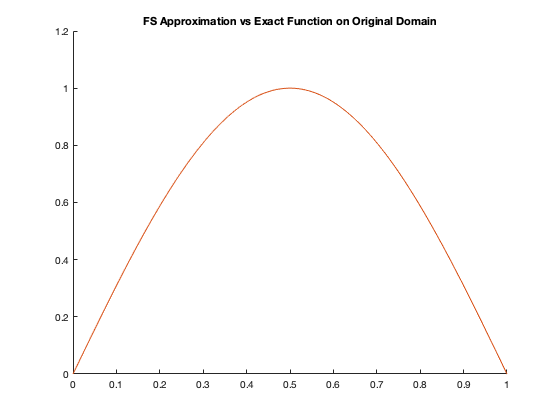


% FFT Procedure
L_FC = D_FC(end) + k; % new period after 1D-FC
C_n = FFT_coeff(phi_FC, L_FC); % ceofficients given by FFT

% Error Calculation
k_err = k/20;
D_err = transpose(0:k_err:L);
phi_FFT = FFT_compute_func(C_n, L_FC, D_err);
phi_exact = phi(D_err);

figure;
hold on;
plot(D_err, phi_exact)
plot(D_err, phi_FFT)
title("FS Approximation vs Exact Function on Original Domain")


err = max(abs(phi_FFT - phi_exact)) % max error on mesh

err =      1.279471203031318e-08
